clear all;
E_steel = 190E9; %[Pa] elastic modulus of steel 

kn = -570; %stiffness negative spring

d = 4; %[mm]
r = d/2 * 1e-3;
L = 150e-3;
I = pi / 4 * r^4;
ks = round(3*E_steel*I/L^3)*2

ks = 4244

stiffness_ratio = ks/kn

stiffness_ratio = -7.4456

Both springs have the same initial position -> if the negative spring exerts a force the position of the base moves in the direction of the displacement 

- Get displacement d

- Results in negative force Fn

- results in displacement of the support (x - xs)

- results in a new real displacement 

- Repeat

x = [-5:0.1:5]*1e-3; %range of motion
x_original = x;

legend_names = []


legend_names =

     []



figure()

iterations = 4

iterations = 4

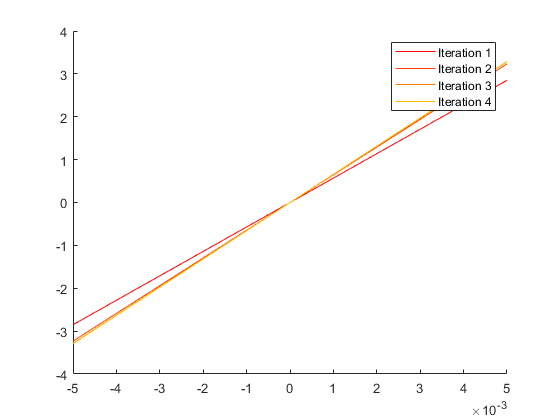


% use colormap parula because it goes blue -> yellow:
cmap = autumn();
% define the color limits:
clim = [-10.4, 1.3];
% define the values to use for line colors:
vals = [clim(1):(clim(2) - clim(1))/iterations:clim(2)];
% indices into cmap of vals, using clim as the upper and lower limits:
idx = 1+round((vals-clim(1))/(clim(2)-clim(1))*(size(cmap,1)-1));
% colors from colormap at those indices:
line_colors = cmap(idx,:);


hold on 
    for i = 1 : iterations
    Fn = -kn*x;
    xs = -Fn/ks; %displacement of the support
    x = x_original - xs; %adjusting displacement 
    legend_names = [legend_names; 'Iteration ' + string(i)];
    plot(x_original,Fn,"Color",line_colors(i,:))
end
legend(legend_names)

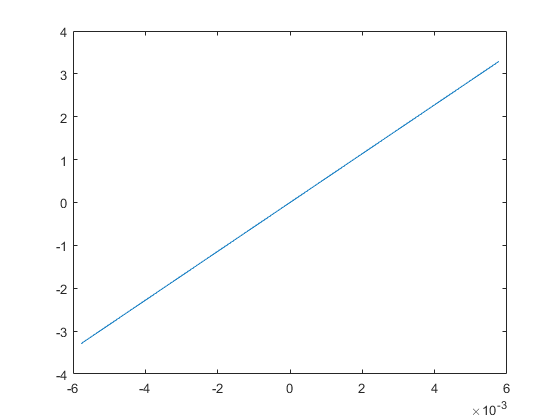

figure()
plot(x,Fn)